# **Script illustrating how to compute with regular hexagonal cone mosaics that are centered at non-zero eccentricities**

*This script illustrates how to compute with regular hex mosaics that are located at an eccentric position. The apporach followed is to generate a regular hex mosaic in which cone spacing is appropriate for the desired eccentricity. The mosaic is zero centered. To compute its response to the a scene, a zero-centered scene is computed by cropping the corresponding patch from the original scene.*

*TODO list:*

*    - adjust optics for the eccentricity of the mosaic.*

*For an alternative eccentric computation approach see: ls_computingWithEccentricityVaryingHexMosaics.mlx*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2019*

# **Step 1.** Define the eccentric mosaic's location and size

% [4 x 4] deg mosaic located in the left eye, 'looking' at a 
% visual field position that is located 5 degrees from the origin,
% at a 135 degree angle (specified counterclockwise with 0 degrees
% pointing at the 3-oclock position)
mosaicEccRadiusDegs = 5;
mosaicEccAngleDegs = 135;
mosaicFOVDegs = [4 4];
mosaicEye = 'left';

% Compute the corresponding ROI rect
roiRect = struct(...
        'xo', mosaicEccRadiusDegs*cosd(mosaicEccAngleDegs),...
        'yo', mosaicEccRadiusDegs*sind(mosaicEccAngleDegs),...
        'width', mosaicFOVDegs(1), ...
        'height', mosaicFOVDegs(2) ...
        );

# **Step 2.** Generate regular hex mosaic with cone spacing&aperture appropriate for the desired eccentricity

% Generate the mosaic
theConeMosaic = coneMosaicHexRegForDesiredEcc(...
        'whichEye', mosaicEye,...
        'eccRadiusDegs', mosaicEccRadiusDegs, ...
        'eccAngleDegs', mosaicEccAngleDegs, ...
        'fovDegs', mosaicFOVDegs);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 133
Scones after making an S-cone free central patch: 8 (added Lcones:84, added Mcones:41)
Scones after pass 1: 6 (added Lcones:1, added Mcones:1)
Scones after pass 2: 6 (added Lcones:0, added Mcones:0)


coneSpacingMicrons = 8.2338

coneApertureMicrons = 5.7637


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Will not create an an S-cone free central patch.
Scones after pass 1: 2408 (added Lcones:1312, added Mcones:657)
Scones after pass 2: 1802 (added Lcones:487, added Mcones:243)
Scones after pass 3: 1642 (added Lcones:117, added Mcones:54)
Scones after pass 4: 1621 (added Lcones:16, added Mcones:7)
Scones after pass 5: 1618 (added Lcones:2, added Mcones:1)
Scones after pass 6: 1618 (added Lcones:0, added Mcones:0)


# **Step 3.** Load a large (20deg) scene and visualize it together with the ROI

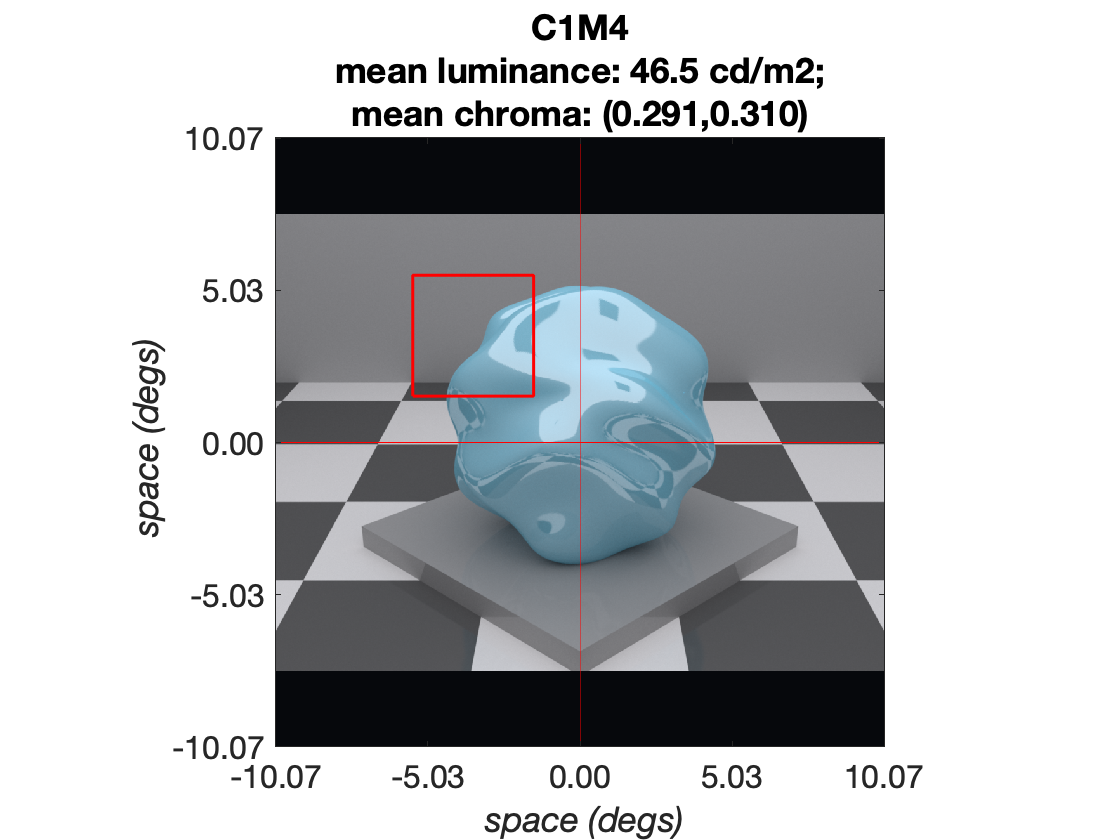

% Load full field scene
load('Blobbie20DegsScene.mat', 'theScene');
visualizeScene(theScene, ...
        'displayRadianceMaps', false, ...
        'spatialSupportInDegs', true, ...
        'roiRectDegs', roiRect);

# **Step 4.** Generate a new scene by cropping the full scene using the desired roiRect

theROIScene = sceneFromROI(theScene, roiRect);

# **Step 5.** Compute the optical image

Note: The optics here are not adjusted for the eccentricity of the mosaic. They are appropriate for foveal eccentricities only. 

theOI = oiCreate('wvf human');
theOI = oiCompute(theOI, theROIScene);

# **Step 6.** Compute the mosaic's response

theIsomerizations = theConeMosaic.compute(theOI, 'currentFlag',false);

# **Step 7.** Visualize mosaic and its activation

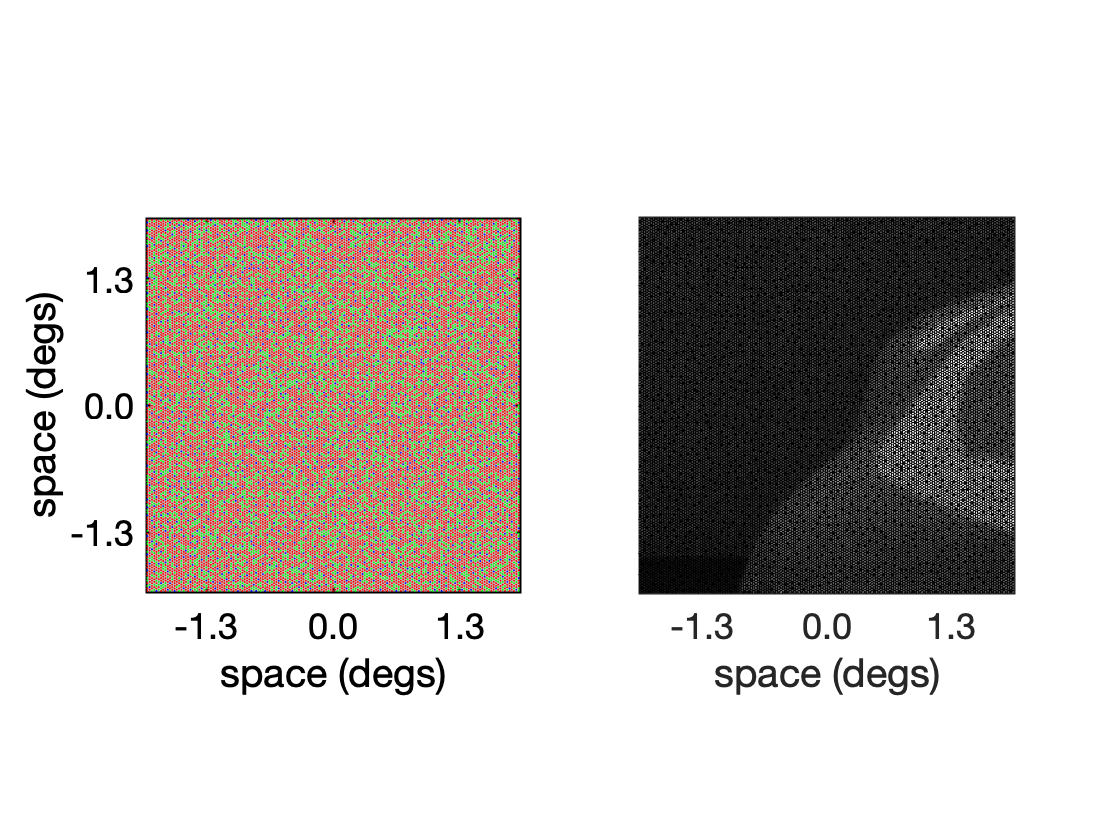

figure(); clf;
ax = subplot(1,2,1);
theConeMosaic.visualizeGrid('axesHandle', ax, ...
    'visualizedConeAperture', 'lightCollectingArea', ... % choose from {'lightCollectingArea', 'geometricArea'}
    'ticksInVisualDegs', true, ...
    'tickInc', max(mosaicFOVDegs)/3);

ax = subplot(1,2,2);
theConeMosaic.renderActivationMap(ax, theIsomerizations, ...
    'mapType', 'modulated disks', ...
    'visualizedConeAperture', 'geometricArea', ...
    'tickInc', 1.3, ...
    'showYLabel', false, ...
    'showYTicks', false, ...
    'colorMap', gray(1024), ...
    'backgroundColor', [0 0 0]);